# สัญญาณและระบบแบบเวลาไม่ต่อเนื่อง (Discrete-time Signal & System)

# ตอนที่ 1 : การสุ่มตัวอย่าง (Signal Sampling)

**คำว่า สุ่ม ในกรณีนี้ไม่ได้มีความหมายในเชิงสุ่มมั่**ว การสุ่มตัวอย่างสัญญาณคือการอ่านสัญญาณแบบเวลาต่อเนื่อง ณ เวลาที่เป็นช่วงๆ เพื่อที่สังเคราะห์สัญญาณแบบเวลาไม่ต่อเนื่อง เราจะกำหนดให้จำนวนครั้งของการสุ่มสัญญาณเท่ากับ $N$ (number of samples)

เพื่อความสม่ำเสมอในการวิเคราะห์และการสังเคราะห์ระบบต่างๆ **การสุ่มตัวอย่างจำเป็นต้องทำเป็นช่วงเวลาที่เท่าๆกัน (fixed time interval)** เราจะเรียกว่าช่วงระยะเวลาระหว่างการสุ่มว่า คาบการสุ่ม $\Delta t$ (sampling period, sample time) หากเราทำการสุ่ม ณ เวลาที่ $t_k$ และ เวลาถัดไปที่สุ่มคือ $t_{k+1}$ผลต่างของเวลาทั้งสองคือ คาบการสุ่ม หรือเขียนเป็นสมการได้ดังต่อไปนี้


$$t_{k+1} -t_k =\Delta t\;\forall \;k\in \left\lbrace 1,\cdots ,N\right\rbrace$$


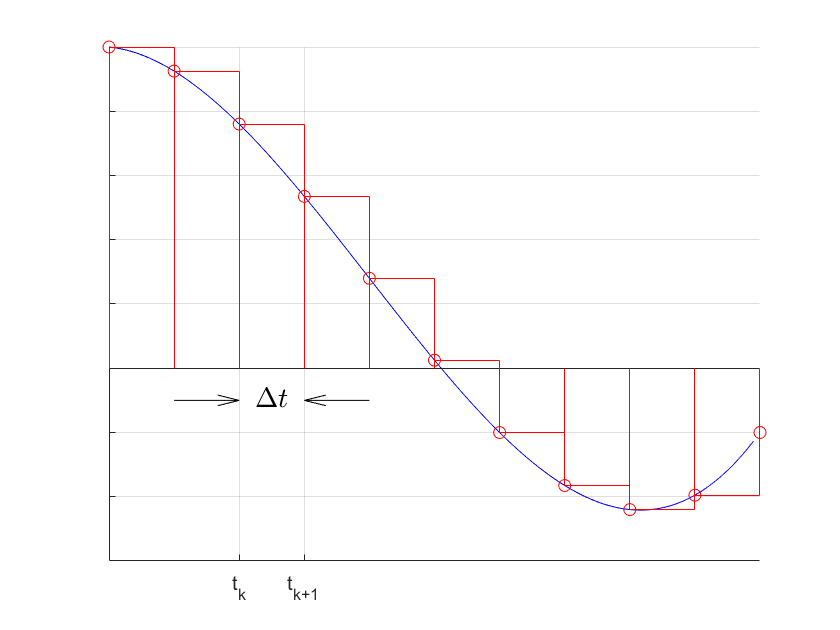

clf;
ax = axes;
hold(ax,'on')
grid(ax,'on')
t_max = 10;
N = 100;
t = linspace(0,t_max-t_max/N,N)';
f = @(t)(0.25*t.^3-3*t.^2-t+50)/10;
plot(ax,t,f(t),'b');
f_s = 1;
dt = 1/f_s;
n = (0:dt:t_max)';
stairs(ax,n,f(n),'r')
stem(ax,n,f(n),'r')
xticks(ax,[2 3]);
xticklabels(ax,{'t_k','t_{k+1}'});
yticklabels(ax,'')
text(ax,2.25,-0.5,'$\Delta t$','FontSize',14,'Interpreter',"latex")
quiver(ax,1,-0.5,1,0,1,'Color','k','MaxHeadSize',2)
quiver(ax,4,-0.5,-1,0,1,'Color','k','MaxHeadSize',2)

หลายครั้ง ความถี่การสุ่ม $f_s$ (sampling frequency) มักถูกใช้ในการอธิบายอัตราการสุ่มตัวอย่างของสัญญาณซึ่งมีค่าเป็นส่วนกลับของคาบการสุ่ม $\Delta t$ หรือ


$$f_s =\frac{1}{\Delta t}$$


## ตัวอย่างที่ 1 การสุ่มตัวอย่าง

กำหนดให้สัญญาณแบบเวลาต่อเนื่องเป็นดังต่อไปนี้


$$y\left(t\right)=\cos \left(2\pi t\right)$$


สัญญาณนี้มีความถี่ที่ $1\;\left\lbrack \textrm{Hz}\right\rbrack$

เนื่องจากไมโครคอนโทรลเลอร์ไม่สามารถประมวลผลสัญญาณแบบเวลาต่อเนื่องได้ เราจำเป็นต้องสุ่มตัวอย่าง ซึ่งเราจะกำหนดให้ความถี่การสุ่มเป็น $1\ldotp 2\;\left\lbrack \textrm{Hz}\right\rbrack$ หรือมีคาบการสุ่มเป็น $\frac{5}{6}\left\lbrack \mathrm{s}\right\rbrack$

กำหนดให้ $y_s \left\lbrack n\right\rbrack$ เป็นสัญญาณแบบเวลาไม่ต่อเนื่อง และ $n$ เป็นตัวแปรอิสระที่อธิบายรอบการคำนวณ เราสามารถเขียนสัญญาณ $y_s$ ณ รอบการคำนวณที่ $n$ให้เท่ากับสัญญาณ $y$ ณ เวลาที่ $\;n\cdot \Delta t$ ซึ่งเขียนป็นสมการได้ดังนี้


$$\begin{array}{l}
y_s \left\lbrack n\right\rbrack =y\left(n\cdot \Delta t\right)\\
y_s \left\lbrack n\right\rbrack =\cos \left(2\pi n\Delta t\right)=\cos \left(\frac{5}{3}\pi n\right)=\cos \left(2\pi n-\frac{1}{3}\pi n\right)
\end{array}$$


เนื่องจาก $n$ เป็นจำนวนเต็ม เราจึงสามารถใช้คุณสมบัติดังต่อไปนี้ได้


$$\cos \left(2\pi n+\theta \right)=\cos \left(\theta \right)$$


ซึ่งทำให้เราได้สัญญาณที่อยู่ในรุปของฟังก์ชั่นดังต่อไปนี้


$$y_s \left\lbrack n\right\rbrack =\cos \left(-\frac{1}{3}\pi n\right)=\cos \left(\frac{1}{3}\pi n\right)$$


## ตัวอย่างที่ 2 : การสังเคราะห์สัญญาณจากค่าที่สุ่มตัวอย่าง

กำหนดให้สัญญาณแบบเวลาไม่ต่อเนื่องเป็นดังต่อไปนี้


$$y_s \left\lbrack n\right\rbrack =\cos \left(\frac{1}{3}\pi n\right)$$


โดยที่มีความถี่การสุ่มเป็น $1\ldotp 2\;\left\lbrack \textrm{Hz}\right\rbrack$ หรือคาบการสุ่มเป็น $\frac{5}{6}\;\left\lbrack \mathrm{s}\right\rbrack$

เราทำการจัดรูปเพื่อใหฟังก์ชันเขียนอยู่ในรูปของ $\Delta t$


$$y_s \left\lbrack n\right\rbrack =\cos \left(\frac{2}{2}\cdot \frac{1}{3}\pi n\cdot \frac{5}{6}\cdot \frac{6}{5}\right)=\cos \left(2\pi \cdot \frac{1}{5}\cdot n\cdot \frac{5}{6}\right)=\cos \left(2\pi \cdot \frac{1}{5}\cdot n\cdot \Delta t\right)$$


ในการสุ่มตัวอย่าง เราแทนค่า $t$ ด้วย $n\Delta t$ ดังนั้นเมื่อเราแทนค่ากลับ เราจะได้สัญญาณแบบเวลาต่อเนื่อง $y_c$ ดังนี้


$$y_c \left(t\right)=\cos \left(2\pi \cdot \frac{1}{5}\cdot t\right)$$


สัญญาณที่ได้สร้างขึ้นมาจากค่าที่สุ่มตัวอย่างมีความถี่เท่ากับ $\frac{1}{5}\;\left\lbrack \textrm{Hz}\right\rbrack$

เราจะสังเกตได้ว่าสัญญาณเดิมจากตัวอย่างที่ 1 นั้นมีความถี่ที่ $1\;\left\lbrack \textrm{Hz}\right\rbrack$ แต่การที่เราสุ่มตัวอย่างด้วยด้วยความถี่ไม่เหมาะสมทำให้สัญญาณที่ถูกสร้างใหม่มีความถี่เป็น $\frac{1}{5}\left\lbrack \textrm{Hz}\right\rbrack$

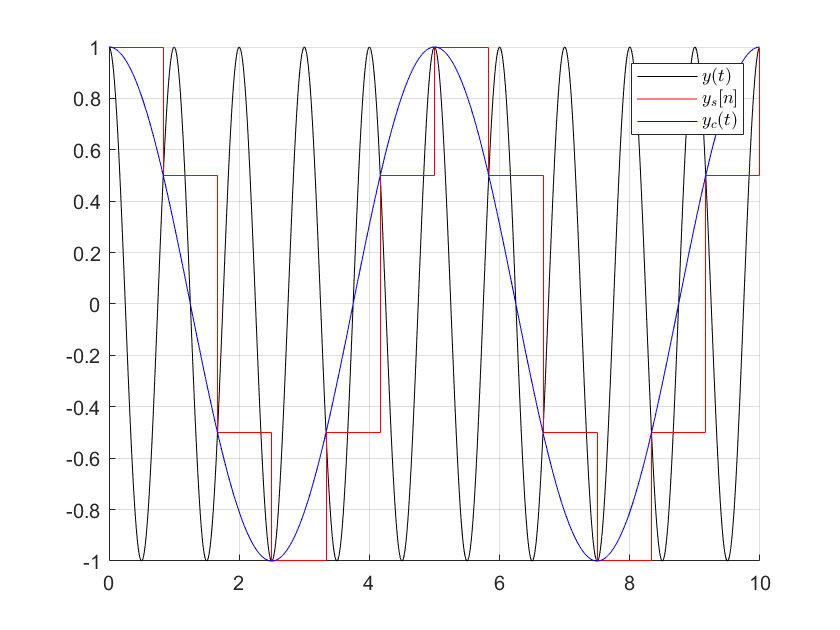

clf;
ax = axes;
hold(ax,'on')
grid(ax,'on')
t_max = 10;
N = 1000;
t = linspace(0,t_max-t_max/N,N)';
y = cos(2*pi*t);
f_s = 1.2;
dt = 1/f_s;
n = 0:dt:t_max;
y_s = cos(2*pi*n);
y_c = cos(2*pi*0.2*t);
plot(ax,t,y,'k');
stairs(ax,n,y_s,'r');
plot(ax,t,y_c,'b');
legend({'$y(t)$','$y_s[n]$','$y_c(t)$'},'Interpreter',"latex")

เพื่อศึกษาช่วงของความถี่ที่เหมาะ เราเปลี่ยนแปลงความถี่การสุ่มและทำเป็นตารางออกมาคร่าวได้ดังนี้

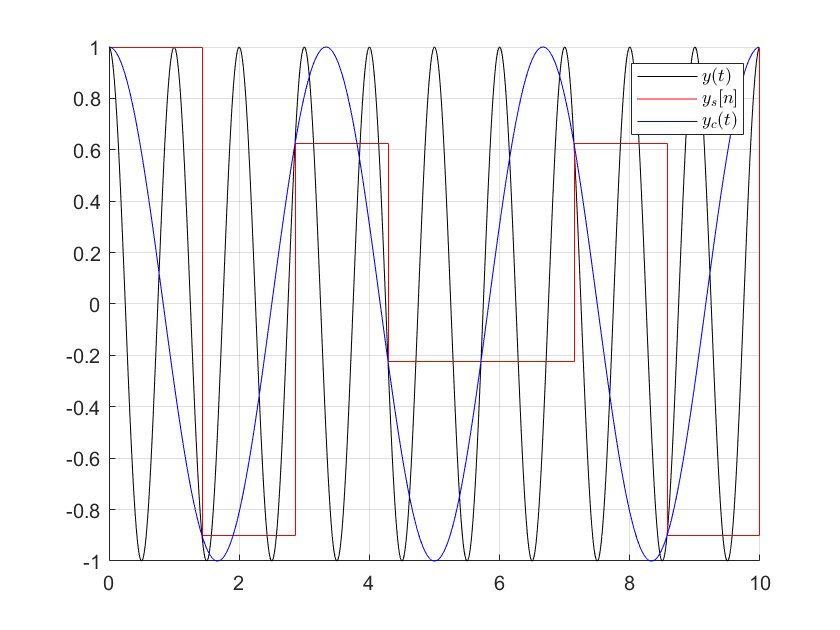

f_s = 0.7;
idx = round(f_s/0.1);
f_c = [0 0 0.1 0.2 0 0.2 0.3 0.2 0.1 0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1]';
clf;
ax = axes;
hold(ax,'on')
grid(ax,'on')
t_max = 10;
N = 1000;
t = linspace(0,t_max-t_max/N,N)';
y = cos(2*pi*t);
dt = 1/f_s;
n = 0:dt:t_max;
y_s = cos(2*pi*n);
y_c = cos(2*pi*f_c(idx)*t);
plot(ax,t,y,'k');
stairs(ax,n,y_s,'r');
plot(ax,t,y_c,'b');
legend({'$y(t)$','$y_s[n]$','$y_c(t)$'},'Interpreter',"latex")

เราจะสังเกตว่าเราไม่สามารถสังเคราะห์สัญญาณกลับมาที่ความถี่เดิมได้ถ้าความถี่การสุ่มมีค่าน้อยกว่า $2\;\left\lbrack \textrm{Hz}\right\rbrack$ อีกความหมายหนึ่งคือการสุ่มตัวอย่างที่น้อยกว่า $2\;\left\lbrack \textrm{Hz}\right\rbrack$ นั้นไม่สามารถใช้กับข้อมูลที่มีความถี่ $1\;\left\lbrack \textrm{Hz}\right\rbrack$ ได้ **ปรากฎการดังกล่าวถูกเรียกว่า การซ้อนทับเชิงความถี่ (Aliasing)**

**ทฤษฎีการสุ่มของไนควิสท์ (Nyquist Sampling Theorem) กล่าวว่า เพื่อที่จะอ่านสัญญาณ เราจำเป็นต้องสุ่มตัวอย่างโดยมีความถี่การสุ่มเป็นอย่างน้อย 2 เท่าของความถี่ของสัญญาณที่ต้องการจะสุ่ม**

หรือในอีกความหมายหนึ่งคือ ความถี่การสุ่มจำเป็นต้องมากกว่าสองเท่าของ bandwidth ของสัญญาณ


$$f_s \ge f_B$$


ในทางปฏิบัติ เราสามารถเพิ่มความถี่การสุ่มเพื่อให้ครอบคลุม bandwidth ของระบบที่อาจจะไม่แน่นอนได้

เราสามารถทำการสุ่มตัวอย่างกับเซนเซอร์และระบบทางกายภาพได้ผ่านอุปกรณ์เช่น ไมโครคอนโทรลเลอร์ (microcontroller) ซึ่งการเขียนโปรแกรมของไมโครคอนโทรลเลอร์ที่ทำให้ทำการสุ่มตัวอย่างอย่างสม่ำเสมอและคงที่นั้นจำเป็นต้องใช้ timer ของไมโครคอนโทรลเลอร์ การสุ่มตัวอย่างนั้นไม่ควรถูกทำใน while loop ที่ไม่มีเวลาแน่นอน 